dt = 0.02;
endTime = 8000;
t = 0:dt:endTime

t = 1.0e+03 *

         0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010


m = 0.2; 
Rad = 1.0;
Cf = 0.47; 
p_0 = 1.0; 
M = 0.029; 
g = 9.8; 
R = 8.31;
T = 300.0; 
V = 4/3 * pi * Rad^3; 
S = pi * Rad^2;

numSteps = length(t);
p = zeros(1, numSteps)

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


v = zeros(1, numSteps)

v =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y = zeros(1, numSteps)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i = 1:numSteps-1
    p(i) = p_0 * exp(-(M * g * y(i)) / (R * T));
    v(i + 1) = v(i) + (1/m) * (p(i) * g * V - m * g - 0.5 * Cf * S * p(i) * v(i)^2) * dt;
    y(i + 1) = y(i) + v(i + 1) * dt;
end

% Display results
display(y);

y = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007


display(v);

v =          0    3.9090    6.6899    7.2948    7.2751    7.2766    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2765    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764    7.2764


display(p);

p =     1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9997    0.9997    0.9997    0.9997    0.9997    0.9997    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9992    0.9992    0.9992    0.9992


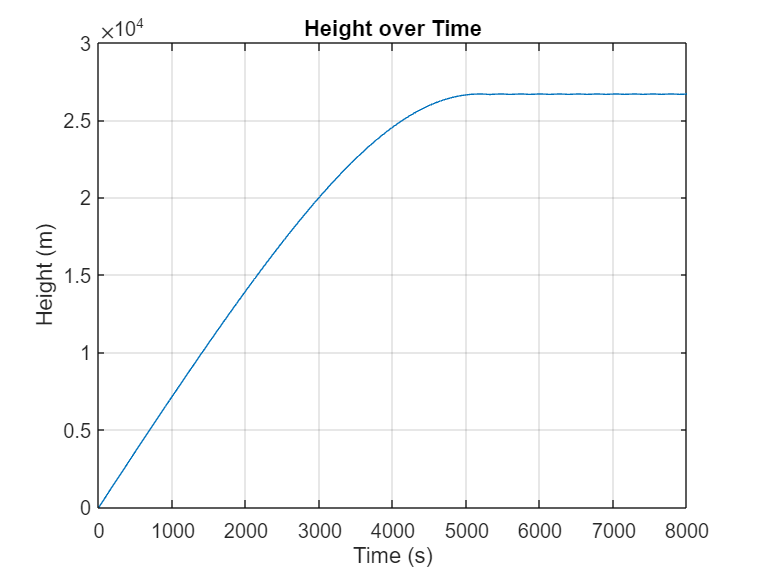

% Plot position over time
figure;
plot(t, y);
xlabel('Time (s)');
ylabel('Height (m)');
title('Height over Time');
grid on;

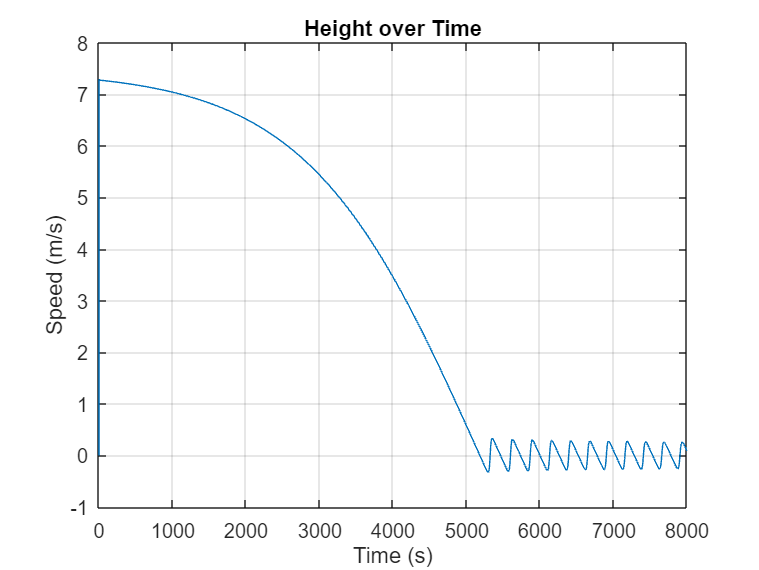


figure;
plot(t, v);
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Height over Time');
grid on;

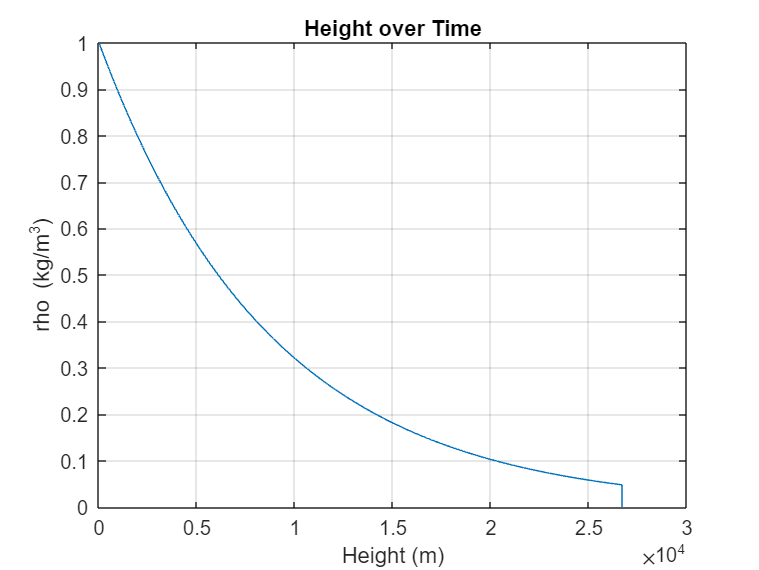


figure;
plot(y, p);
xlabel('Height (m)');
ylabel('rho (kg/m^3)');
title('Height over Time');
grid on;